% Tensor Network B-splines two dimensional test
clear all

rng(1)



tt = 0:0.01:1;
[X,Y] = meshgrid(tt,tt);

coords = [X(:),Y(:)];

f = rastriginfcn(coords);

min(f)

ans = 0

max(f)

ans = 0.8050

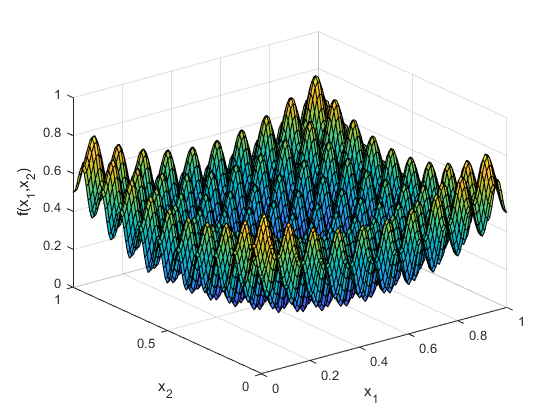


figure
surf(tt,tt,reshape(f,[length(tt) length(tt)]),'LineStyle','-')
xlabel('x_1')
ylabel('x_2')
zlabel('f(x_1,x_2)')

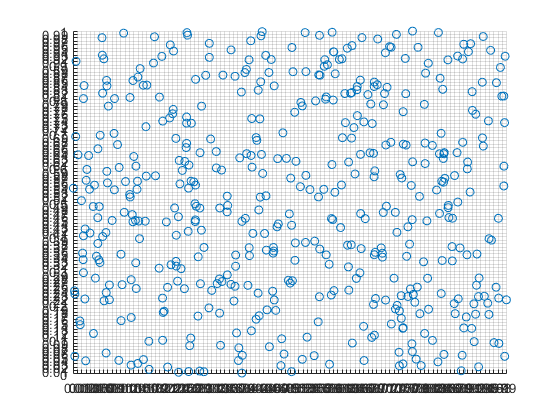


featurez = (rand(500,2));
zeta = rastriginfcn(featurez);

scatter(featurez(:,1), featurez(:,2))

ticks = 0:1/100:1;
xticks(ticks);
yticks(ticks);
grid on

[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 97;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

maxrank = 3;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);

lambdaz=[0.01 0.01 ;0.01 100 ;100 0.01 ;100 100] 

lambdaz =     0.0100    0.0100
    0.0100  100.0000
  100.0000    0.0100
  100.0000  100.0000



for iter = 1:4

    lambda = lambdaz(iter,:);
tic
difforder=2;
MAXITR = 50;
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
toc
trainerror = res1(end)

yhat = evalspline(TN,coords,n,m);

store{iter} = yhat;
RMSE(iter) = sqrt(immse(f,yhat));
end

Elapsed time is 0.814149 seconds.


trainerror = 1.8833e-05

Elapsed time is 0.437960 seconds.


trainerror = 0.0034

Elapsed time is 0.237250 seconds.


trainerror = 0.0033

Elapsed time is 0.231633 seconds.


trainerror = 0.0091

% figure
% hold on
% plot(log(res1),'linewidth',2,"LineStyle","--")
% plot(log(res2),'linewidth',2,"LineStyle","--")
% plot(log(res1+res2),'linewidth',3)
% hold off
% legend('Prediction cost', 'Penalty cost', 'Total cost')
% xlabel('Sweep')
% ylabel('log(MSE)')




figz = figure

figz =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


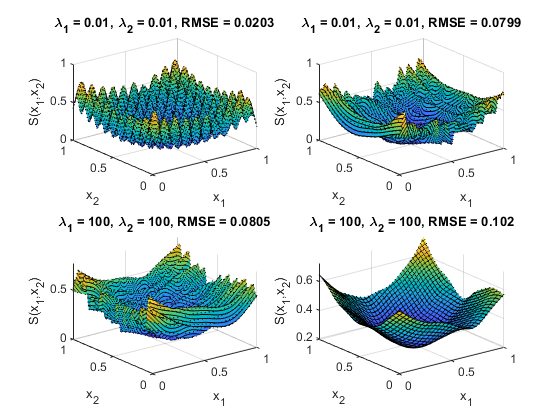


for it = 1:4
    
subplot(2,2,it)

S = surf(tt,tt,reshape(store{it},[length(tt) length(tt)]), 'EdgeColor','black');
xlabel('x_1')
ylabel('x_2')
zlabel('S(x_1,x_2)')
set(S,'LineStyle',':')
title(['\lambda_1 = ' num2str(lambdaz(it,1)) ', \lambda_2 = ' num2str(lambdaz(it,1)) ', RMSE = ' num2str(RMSE(it),3)])

end

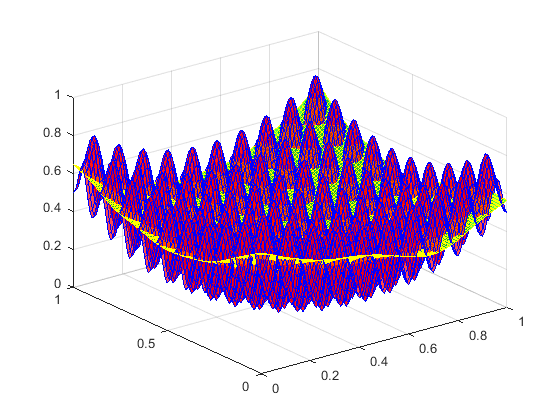



figure
surf(tt,tt,reshape(f,[length(tt) length(tt)]), 'FaceColor','r', 'FaceAlpha',0.7, 'EdgeColor','b')
hold on
surf(tt,tt,reshape(yhat,[length(tt) length(tt)]), 'FaceColor','g', 'FaceAlpha',0.7, 'EdgeColor','y')
hold off

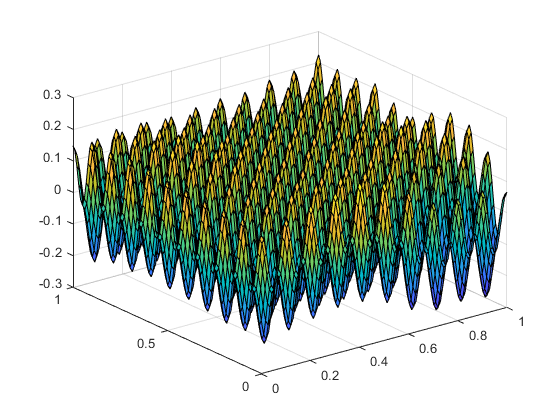


surf(tt,tt,reshape(yhat-f,[length(tt) length(tt)]))


RMSE = sqrt(immse(f,yhat))

RMSE = 0.1016


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 0.06


output-min(output)

ans =     1.6673
    0.9836
    0.7063
    1.2425
    2.0331
    1.8186
    1.9457
    0.8451
    1.1357
    1.8516


ccc = parula(102)

ccc =     0.2422    0.1504    0.6603
    0.2474    0.1589    0.6907
    0.2523    0.1691    0.7184
    0.2568    0.1797    0.7455
    0.2613    0.1897    0.7730
    0.2655    0.1996    0.8003
    0.2693    0.2101    0.8263
    0.2725    0.2216    0.8499
    0.2751    0.2340    0.8707
    0.2772    0.2474    0.8889



normz = (output-min(output))/max(output-min(output))

normz =     0.6574
    0.3878
    0.2785
    0.4899
    0.8016
    0.7170
    0.7671
    0.3332
    0.4478
    0.7300


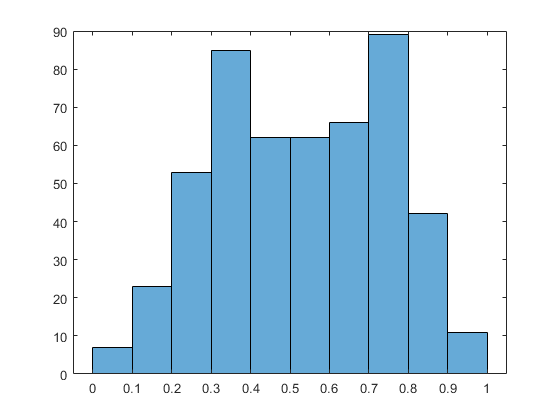


histogram(normz)

indd = round(normz*100)

indd =     66
    39
    28
    49
    80
    72
    77
    33
    45
    73


  Name        Size            Bytes  Class     Attributes

  indd      500x1              4000  double              



ccc(indd+1,:)

ans =     0.4555
    0.1203
    0.1810
    0.0227
    0.8998
    0.6672
    0.8216
    0.1598
    0.0270
    0.7002



output = sin(pi*featurez(:,1)).*sin(pi*featurez(:,2))+ 0.5*sin(2*pi*featurez(:,1))+0.25*sin(4*pi*featurez(:,1))+0.5*sin(8*pi*featurez(:,1)).*sin(8*pi*featurez(:,2));


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 14;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

maxrank = 10;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);

lambda = [1 1]

lambda =      1     1


tic
difforder=1;
MAXITR = 50;
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,output,MAXITR,[],lambda,difforder);
toc

Elapsed time is 0.063266 seconds.



yhat = evalspline(TN,coords,n,m);

last = figure

last =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 50
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties



subplot(1,2,1)


DD = scatter3(featurez(:,1),featurez(:,2),output,[],ccc(indd+1,:) ,'filled','MarkerEdgeColor','k')

DD =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: [0 0 0]
    MarkerFaceColor: 'flat'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×500 double]
              YData: [1×500 double]
              ZData: [1×500 double]
              CData: [500×3 double]

  Show all properties


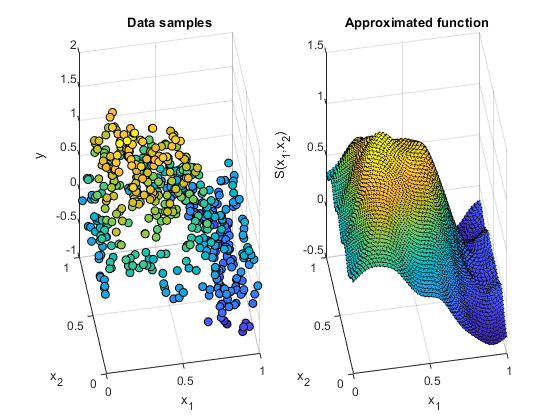

% view(60,60)
xlabel('x_1')
ylabel('x_2')
zlabel('y')
title('Data samples')

view([-10 30]);

subplot(1,2,2)

S = surf(tt,tt,reshape(yhat,[length(tt) length(tt)]), 'EdgeColor','black');
xlabel('x_1')
ylabel('x_2')
zlabel('S(x_1,x_2)')
set(S,'LineStyle',':')
title('Approximated function')
zlabel('S(x_1,x_2)')

view([-10 30]);